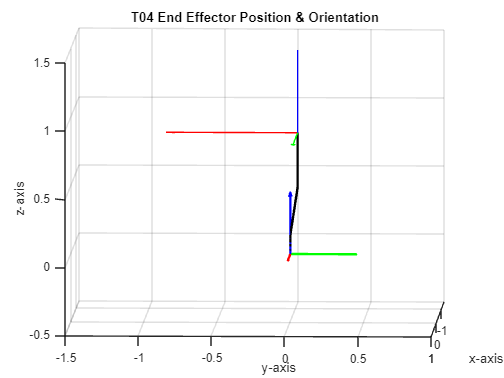

function PlotRotatingAxes(T_new)
quiver3(T_new(1, 4), T_new(2, 4), T_new(3, 4), T_new(1, 1), T_new(2, 1), T_new(3, 1), 'r');
hold on
quiver3(T_new(1, 4), T_new(2, 4), T_new(3, 4), T_new(1, 2), T_new(2, 2), T_new(3, 2), 'g');
quiver3(T_new(1, 4), T_new(2, 4), T_new(3, 4), T_new(1, 3), T_new(2, 3), T_new(3, 3), 'b');
hold off
xlabel('x-axis');
ylabel('y-axis');
zlabel('z-axis');

grid on;
xlim([-1.5 1])
ylim([-1.5 1])
zlim([-.5 1.5])
view([108.11 15.28])
end

TU0 = eye(4);
theta_1 = 90;
theta_2 = 0;
theta_3 = -90;
theta_4 = 0;

theta_1_rad = theta_1*pi/180;
theta_2_rad = theta_2*pi/180;
theta_3_rad = theta_3*pi/180;
theta_4_rad = theta_4*pi/180;

function PlotLine(start,finish)
hold on
x = [start(1,4),finish(1,4)];
y = [start(2,4),finish(2,4)];
z = [start(3,4),finish(3,4)];
plot3(x, y, z,"k","LineWidth",2)
hold off
end

function PlotFixedAxes()
% figure(FigNum);
hold on
quiver3(0, 0, 0, .5, 0, 0, 'r', 'LineWidth', 2);
quiver3(0, 0, 0, 0, .5, 0, 'g', 'LineWidth', 2);
quiver3(0, 0, 0, 0, 0, .5, 'b', 'LineWidth', 2);
title('T04 End Effector Position & Orientation');
grid on;
end

steps = 30;

for i=0:steps
    [T01, T02, T03, T04] = QArmForwardKinematics(theta_1_rad*i/steps,theta_2_rad*i/steps,theta_3_rad*i/steps,theta_4_rad*i/steps);
    pos_final = T04;
    hold off
    PlotRotatingAxes(pos_final);
    hold on
    % PlotLine(TU0,T04)
    PlotLine(TU0,T01)
    PlotLine(T01,T02)
    PlotLine(T02,T03)
    PlotLine(T03,T04)
    PlotFixedAxes()

    pause(0.2)
end